Semi-Definite Problem |Ax -b |^2 -> min

clear all
close all
A = [1 -1; 1 1];
b = [-2; -2];
t = sdpvar(1);
x = sdpvar(2, 1);


% Objective function (must include all of the unknown variables)
%F = [0 0 1]*[X; t];
h = t;
% Constraints
C = [eye(2), A*x - b;
    (A*x-b)', t];
u = [1; 2];
l = [-1; -2];

constr = [C >= 0; x <= u; x >= l]; % interpret >= as semidefinite matrix

%Settings
opts = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 55);
optimize(constr, h, opts);


 num. of constraints =  3
 dim. of sdp    var  =  3,   num. of sdp  blk  =  1
 dim. of linear var  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+00|3.8e+00|7.0e+02| 8.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.999|1.8e-06|4.6e-02|6.2e+01| 4.926053e+01 -8.111524e+00| 0:0:00| chol  1  1 
 2|0.982|0.992|3.1e-07|4.5e-03|1.3e+00|-9.830452e-01 -2.175265e+00| 0:0:00| chol  1  1 
 3|0.983|0.980|2.4e-07|5.0e-04|2.3e-02|-1.982997e+00 -1.997791e+00| 0:0:00| chol  1  1 
 4|0.989|0.989|1.7e-08|4.7e-05|2.6e-04|-1.999807e+00 -1.999284e+00| 0:0:00| chol  1  1 
 5|0.988|0.988|1.6e-09|5.6e-07|3.3e-06|-1.99

y = value([x; t])

y =    -1.0000
    0.0000
    2.0000


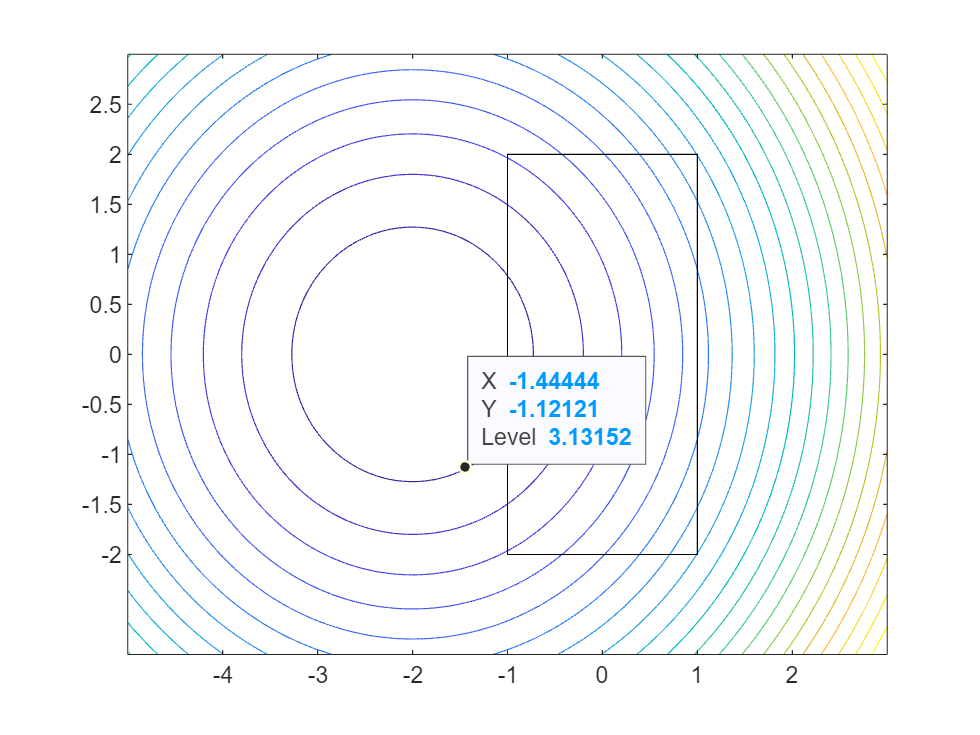

x = linspace(-5, 3, 100);
y = linspace(-3, 3, 100);
[X,Y] = meshgrid(x,y);
Z = (A(1,1)*X + A(1,2)*Y - b(1)).^2 + (A(2,1)*X + A(2,2)*Y - b(2)).^2;
contour(X,Y,Z, 20)
hold on
rectangle('Position',[l(1) l(2) u(1) - l(1) u(2) - l(2)])